
Single objective optimization:
2 Variables
2 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1            597       13578.9            0      0
    2           1132       13578.2     2.72e-07      0    3           1655       13578.2    5.795e-05      0
Optimization finished: average change in the fitness value less than options.FunctionTolerance and constraint violation is less than options.ConstraintTolerance.


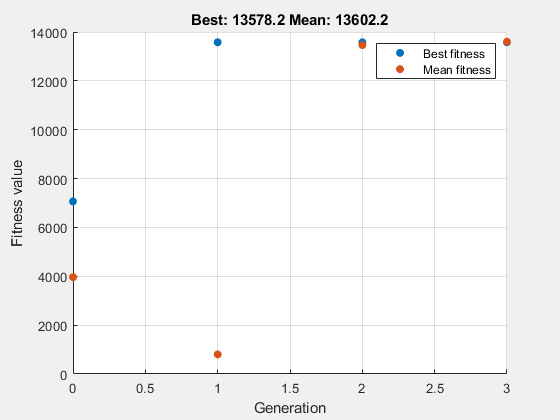

objectiveFcn = @(x) 100 * (x(1)^2 - x(2))^2 + (1 - x(1))^2;

nonlincon = @(x) deal(...
    [x(1) * x(2) + x(1) - x(2) + 1.5; 10 - x(1) * x(2)], ...
    []);
% Границы переменных
lb = [0, 0];
ub = [1, 13];

options = optimoptions('ga', ...
    'Display', 'iter', ...
    'PlotFcn', @gaplotbestf, ...
    MaxGenerations=10);

[x_opt, fval] = ga(objectiveFcn, 2, [], [], [], [], lb, ub, nonlincon, options);

disp('Оптимальное решение:');

Оптимальное решение:


disp(x_opt);

    0.8122   12.3122



disp('Минимальное значение целевой функции:');

Минимальное значение целевой функции:


disp(fval);

   1.3578e+04



## поверхность

x_opt(1)

ans = 0.8122

x_opt(2)

ans = 12.3122

fval

fval = 1.3578e+04

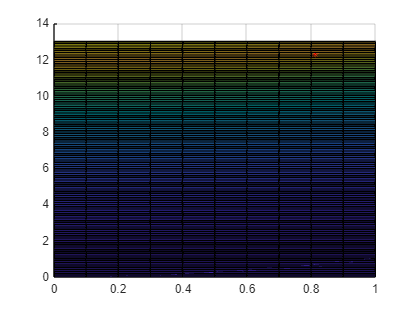

figure
[x, y] = meshgrid(0:0.1:1, 0:0.1:13);
f = 100 * (x.^2 - y).^2 + (1 - x).^2;
hold on
surface(x, y, f);
plot3(x_opt(1),x_opt(2),fval,'*r')
grid on;